% PROBLEM 1

close all
clear
clc

% Define the system parameters
m1 = 20; % kg
m2 = 40; % kg
m3 = 30; % kg
k1 = 2000; % N/m
k2 = 4000; % N/m

% Define the system matrices
Ap = [0 0 0 1 0 0;
      0 0 0 0 1 0;
      0 0 0 0 0 1;
      -k1/m1 k1/m1 0 0 0 0;
      k1/m2 (-k1-k2)/m2 k2/m2 0 0 0;
      0 k2/m3 -k2/m3 0 0 0]

Ap =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
 -100.0000  100.0000         0         0         0         0
   50.0000 -150.0000  100.0000         0         0         0
         0  133.3333 -133.3333         0         0         0


Bp = [0; 0; 0; 1/m1; 0; 0]

Bp =          0
         0
         0
    0.0500
         0
         0


Dp = [0; 0; 0; 1/m1; 0; 0]

Dp =          0
         0
         0
    0.0500
         0
         0


Cp2 = [0 0 1 0 0 0]

Cp2 =      0     0     1     0     0     0


By2 = 0

By2 = 0

Dy = 0

Dy = 0

% Lumped system representation
A = Ap;
B = [Dp Bp];
C = [zeros(size(Cp2)); Cp2];
D = [Dy zeros(size(By2)); zeros(size(Dy)) By2];
S = ltisys(A, B, C, D)

S =          0         0         0    1.0000         0         0         0         0    6.0000
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
 -100.0000  100.0000         0         0         0         0    0.0500    0.0500         0
   50.0000 -150.0000  100.0000         0         0         0         0         0         0
         0  133.3333 -133.3333         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      -Inf



% State-feedback controller G1 to minimize the energy-to-peak gain Γep
r = size(By2);
obj = [0 0 0 1]; % Optimal H2 control design objective
region = lmireg; % h (half-plane) --> l (LHP, i.e., Re(z) < x0) --> -1 (x0 = -1)



Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


[g1opt, g2opt, G1, Scl, X] = msfsyn(S, r, obj, region)


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8                   0.123781
     9                   0.101980
    10                   0.101980
    11                   0.028857
    12                   0.028857
    13                   0.028857
    14                   0.012000
    15                   0.012000
    16                   0.010372
    17                   0.010372
    18                   0.010372
    19               6.093835e-03
    20               6.093835e-03
    21               6.093835e-03
    22               3.043563e-03
    23               3.043563e-03
    24               3.043563e-03
    25               1.240950e-03
    26               1.240950e-03
    27               1.231455e-03
    28               3.550594e-04
    29               2.

g2opt = 9.5736e-04

G1 = 1.0e+11 *

   -0.0008   -0.2312   -1.9312   -0.0000   -0.0024   -0.0996


Scl = 1.0e+09 *

         0         0         0    0.0000         0         0         0    0.0000
         0         0         0         0    0.0000         0         0         0
         0         0         0         0         0    0.0000         0         0
   -0.0038   -1.1562   -9.6558   -0.0000   -0.0120   -0.4980    0.0000         0
    0.0000   -0.0000    0.0000         0         0         0         0         0
         0    0.0000   -0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0      -Inf


X = 1.0e+06 *

    0.0003    0.0000   -0.0000   -0.0080   -0.0002   -0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0080    0.0000   -0.0000    1.3121   -0.0003   -0.0000
   -0.0002   -0.0000    0.0000   -0.0003    0.0002    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000



% Closed-loop system
Acl = Ap + Bp*G1

Acl = 1.0e+09 *

         0         0         0    0.0000         0         0
         0         0         0         0    0.0000         0
         0         0         0         0         0    0.0000
   -0.0038   -1.1562   -9.6558   -0.0000   -0.0120   -0.4980
    0.0000   -0.0000    0.0000         0         0         0
         0    0.0000   -0.0000         0         0         0


Scl = ss(Acl, [Dp zeros(size(Bp))], C, D)

Scl =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           0           0           1           0           0
   x2           0           0           0           0           1           0
   x3           0           0           0           0           0           1
   x4  -3.805e+06  -1.156e+09  -9.656e+09   -1.15e+04  -1.205e+07   -4.98e+08
   x5          50        -150         100           0           0           0
   x6           0       133.3      -133.3           0           0           0
 
  B = 
         u1    u2
   x1     0     0
   x2     0     0
   x3     0     0
   x4  0.05     0
   x5     0     0
   x6     0     0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   0   0
   y2   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


h2_norm = norm(Scl, 2)

h2_norm = 1.8822e-11


% Verification
if((h2_norm < g2opt) && all(real(eig(Acl)) < -1.0))
    disp('Verification of H2 norm and pole location constraints successful!')
else
    disp('Verification of H2 norm and pole location constraints failed!')
end

Verification of H2 norm and pole location constraints successful!


%CHECK

% Add parser and solver to path
addpath(genpath('C:\Users\csamak\Downloads\MathWorks\Toolboxes\archives\required\YALMIP'))
addpath(genpath('C:\Users\csamak\Downloads\MathWorks\Toolboxes\archives\required\SeDuMi'))

% Define the solver settings (use an LMI solver like YALMIP with a solver of your choice)
options = sdpsettings('verbose', 1, 'solver', 'sedumi');

gamma_bar = sdpvar(1, 1); % Define the LMI variable
P = sdpvar(size(Acl,1), size(Acl,2)); % Define the LMI variable
LMI_1 = [-gamma_bar*eye(size(C)) C*P*C'; C*P*C' -eye(size(C))] <= 0; % Define the LMI constraint
LMI_2 = Acl*P + P*Acl' + [Dp zeros(size(Bp))]*[Dp zeros(size(Bp))]' <= 0; % Define the LMI constraint
LMI_3 = P >= 0; % Define the LMI constraint
Objective = gamma_bar; % Set up the objective
solution = optimize([LMI_1, LMI_2, LMI_3], Objective, options); % Solve the LMI problem

The coefficient matrix is not full row rank, numerical problems may occur.
SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 22, order n = 17, dim = 77, blocks = 3
nnz(A) = 109 + 0, nnz(ADA) = 442, nnz(L) = 232
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.38E+19 0.000
  1 :  -3.38E-12 3.39E+18 0.000 0.0774 0.9900 0.9900   1.00 51  2  3.4E+09
  2 :  -1.44E-11 7.67E+17 0.000 0.2264 0.9000 0.9000   1.00 13 22  7.7E+08
  3 :  -4.25E-11 2.16E+17 0.000 0.2814 0.9000 0.9000   1.00 11 22  2.2E+08
  4 :  -7.64E-11 4.37E+16 0.000 0.2026 0.9000 0.9000   1.00  5 26  4.5E+07
  5 :  -2.84E-10 2.62E+16 0.000 0.5981 0.9000 0.9000   1.00  7 22  2.7E+07
  6 :  -5.72E-10 2.14E+16 0.000 0.8162 0.9000 0.9000   1.00  8 25  2.3E+07
  7 :  -7.97E-10 1.69E+16 0.000 0.7893 0.9000 0.9000   1.00 11 15  3.1E+07
  8 :  -8.01E-10 1.39E+16 0.000 0.8264 0.9000 0.9000   1.00 10  8  2.8E+07
  9 :  -1.09E-0

if solution.problem == 0
    gamma_bar = value(gamma_bar); % Extract the optimal solution
end

% Define the lumped (disturbance + control) input
t = 0:0.01:10;
w_amplitude = 100.0;
w_duration = 2;
w_pulse = w_amplitude * (t >= 0 & t <= w_duration);
u = zeros(size(w_pulse));
w = [w_pulse; u];

% Simulate the open-loop system response
Sol = ss(A, B, C, D)

Sol =
 
  A = 
           x1      x2      x3      x4      x5      x6
   x1       0       0       0       1       0       0
   x2       0       0       0       0       1       0
   x3       0       0       0       0       0       1
   x4    -100     100       0       0       0       0
   x5      50    -150     100       0       0       0
   x6       0   133.3  -133.3       0       0       0
 
  B = 
         u1    u2
   x1     0     0
   x2     0     0
   x3     0     0
   x4  0.05  0.05
   x5     0     0
   x6     0     0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   0   0
   y2   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


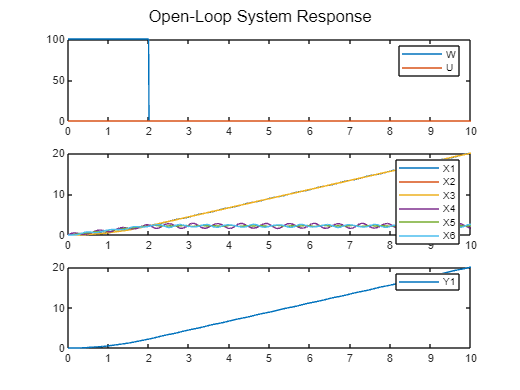

[y_ol, t_out, x_ol] = lsim(Sol, w', t);

% Plot the results
figure;
sgtitle('Open-Loop System Response');
subplot(3, 1, 1);
plot(t, w(1, :), t, w(2, :));
legend('W', 'U');
subplot(3, 1, 2);
plot(t, x_ol(:, 1), ...
     t, x_ol(:, 2), ...
     t, x_ol(:, 3), ...
     t, x_ol(:, 4), ...
     t, x_ol(:, 5), ...
     t, x_ol(:, 6) ...
     );
legend('X1', 'X2', 'X3', 'X4', 'X5', 'X6');
subplot(3, 1, 3);
plot(t, y_ol(:, 2));
legend('Y1');


% Simulate the closed-loop system response
Scl = ss(Acl, [Dp zeros(size(Bp))], C, D)

Scl =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           0           0           1           0           0
   x2           0           0           0           0           1           0
   x3           0           0           0           0           0           1
   x4  -3.805e+06  -1.156e+09  -9.656e+09   -1.15e+04  -1.205e+07   -4.98e+08
   x5          50        -150         100           0           0           0
   x6           0       133.3      -133.3           0           0           0
 
  B = 
         u1    u2
   x1     0     0
   x2     0     0
   x3     0     0
   x4  0.05     0
   x5     0     0
   x6     0     0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   0   0
   y2   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


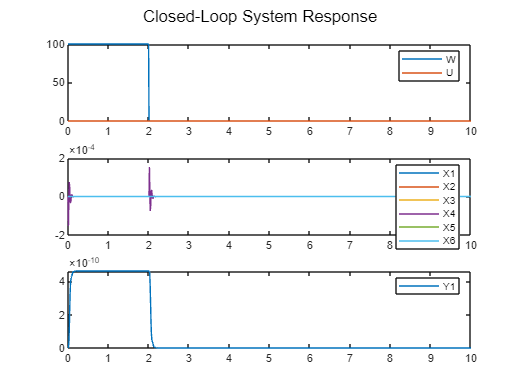

[y_cl, t_out, x_cl] = lsim(Scl, w', t);

% Plot the results
figure;
sgtitle('Closed-Loop System Response');
subplot(3, 1, 1);
plot(t, w(1, :), t, w(2, :));
legend('W', 'U');
subplot(3, 1, 2);
plot(t, x_cl(:, 1), ...
     t, x_cl(:, 2), ...
     t, x_cl(:, 3), ...
     t, x_cl(:, 4), ...
     t, x_cl(:, 5), ...
     t, x_cl(:, 6) ...
     );
legend('X1', 'X2', 'X3', 'X4', 'X5', 'X6');
subplot(3, 1, 3);
plot(t, y_cl(:, 2));
legend('Y1');

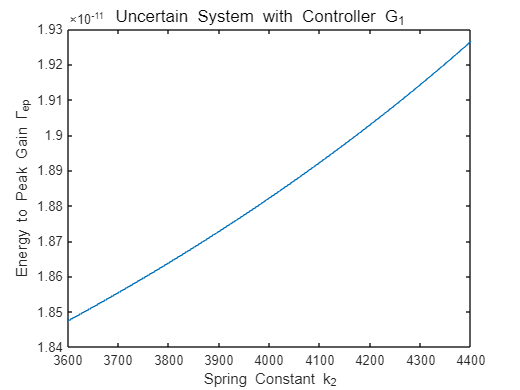

% Define uncertain system parameters
m1 = 20; % kg
m2 = 40; % kg
m3 = 30; % kg
k1 = 2000; % N/m
i = 1;
for k2 = 3600:1:4400 % N/m
    % Define the system matrices
    Ap = [0 0 0 1 0 0;
          0 0 0 0 1 0;
          0 0 0 0 0 1;
          -k1/m1 k1/m1 0 0 0 0;
          k1/m2 (-k1-k2)/m2 k2/m2 0 0 0;
          0 k2/m3 -k2/m3 0 0 0];
    Bp = [0; 0; 0; 1/m1; 0; 0];
    Dp = [0; 0; 0; 1/m1; 0; 0];
    Cp2 = [0 0 1 0 0 0];
    By2 = 0;
    Dy = 0;
    % Lumped system representation
    A = Ap;
    B = [Dp Bp];
    C = [zeros(size(Cp2)); Cp2];
    D = [Dy zeros(size(By2)); zeros(size(Dy)) By2];
    % Closed-loop system
    Acl = Ap + Bp*G1;
    Scl = ss(Acl, [Dp zeros(size(Bp))], C, D);
    h2_norm(i) = norm(Scl, 2);
    i = i+1;
end

figure;
sgtitle('Uncertain System with Controller G_1');
plot(3600:1:4400, h2_norm)
xlabel('Spring Constant k_2')
ylabel('Energy to Peak Gain Γ_ep')

% Define the system parameters
m1 = 20; % kg
m2 = 40; % kg
m3 = 30; % kg
k1 = 2000; % N/m
k2 = 4000; % N/m

% Define the system matrices
Ap = [0 0 0 1 0 0;
      0 0 0 0 1 0;
      0 0 0 0 0 1;
      -k1/m1 k1/m1 0 0 0 0;
      k1/m2 (-k1-k2)/m2 k2/m2 0 0 0;
      0 k2/m3 -k2/m3 0 0 0]

Ap =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
 -100.0000  100.0000         0         0         0         0
   50.0000 -150.0000  100.0000         0         0         0
         0  133.3333 -133.3333         0         0         0


Bp = [0; 0; 0; 1/m1; 0; 0]

Bp =          0
         0
         0
    0.0500
         0
         0


Dp = [0; 0; 0; 1/m1; 0; 0]

Dp =          0
         0
         0
    0.0500
         0
         0


Cp2 = [0 0 1 0 0 0]

Cp2 =      0     0     1     0     0     0


By2 = 0

By2 = 0

Dy = 0

Dy = 0


% Lumped system representation
A = Ap;
B = [Dp Bp];
C = [zeros(size(Cp2)); Cp2];
D = [Dy zeros(size(By2)); zeros(size(Dy)) By2];

% System matrices in affine form
A0 = [0 0 0 1 0 0;
      0 0 0 0 1 0;
      0 0 0 0 0 1;
      -k1/m1 k1/m1 0 0 0 0;
      k1/m2 (-k1)/m2 1/m2 0 0 0;
      0 1/m3 -1/m3 0 0 0]

A0 =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
 -100.0000  100.0000         0         0         0         0
   50.0000  -50.0000    0.0250         0         0         0
         0    0.0333   -0.0333         0         0         0


A1 = [0 0 0 0 0 0;
      0 0 0 0 0 0;
      0 0 0 0 0 0;
      0 0 0 0 0 0;
      0 -1 1 0 0 0;
      0 1 -1 0 0 0]

A1 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0    -1     1     0     0     0
     0     1    -1     0     0     0


B0 = B

B0 =          0         0
         0         0
         0         0
    0.0500    0.0500
         0         0
         0         0


C0 = C

C0 =      0     0     0     0     0     0
     0     0     1     0     0     0


D0 = D

D0 =      0     0
     0     0



% Uncertain LTI system in affine form
S0 = ltisys(A0, B0, C0, D0, 1)

S0 =          0         0         0    1.0000         0         0         0         0    6.0000
         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0
 -100.0000  100.0000         0         0         0         0    0.0500    0.0500         0
   50.0000  -50.0000    0.0250         0         0         0         0         0         0
         0    0.0333   -0.0333         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      -Inf


S1 = ltisys(A1, zeros(size(B0)), zeros(size(C0)), zeros(size(D0)), 0)

S1 =    0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   6.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 0.0000i  


% Parameter vector
P = pvec('box', [3600, 4400])

P =            1        3600        4400           0           0
           1           0           0           0           0



% Affine system
affsys = psys(P, [S0, S1])

affsys = 1.0e+03 *

     -Inf + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0060 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0010i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0060 + 0.0000i   0.0010 + 0.0000i   3.6000 + 0.0000i   4.4000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0020 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0010i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0010 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 


% State-feedback controller G2 to minimize the energy-to-peak gain Γep
r = size(By2);
obj = [0 0 0 1]; % Optimal H2 control design objective
region = lmireg; % h (half-plane) --> l (LHP, i.e., Re(z) < x0) --> -1 (x0 = -1)



Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


Select a region among the following:

h)   Half-plane
d)   Disk 
c)   Conic sector 
e)   Ellipsoid 
p)   Parabola 
s)   Horizontal strip 
m)   Matrix description of the LMI region
q)   Quit


[g1opt, g2opt, G2, Scl, X] = msfsyn(affsys, r, obj, region)


 Optimization of   0.000 * G^2 +  1.000 * H^2 :
 ----------------------------------------------

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15
    16
    17
    18
    19
    20                   0.127040
    21                   0.064668
    22                   0.064668
    23                   0.064668
    24                   0.039339
    25                   0.039339
    26                   0.035609
    27                   0.035609
    28                   0.035609
    29                   0.020190
    30                   0.020190
    31                   0.020190
    32                   0.010889
    33                   0.010889
    34                   0.010889
    35               5.447353e-03
    36               5.447353e-03
    37               5.447353e-03
    38               2.609418e-03
    39 

g2opt = 9.7798e-04

G2 = 1.0e+11 *

   -0.0021   -2.6316   -2.5782   -0.0000   -0.0138   -0.0788


Scl = 1.0e+10 *

      -Inf         0         0         0         0    0.0000         0         0         0    0.0000         0         0         0         0    0.0000         0         0         0    0.0000
    0.0000         0         0         0         0         0    0.0000         0         0         0         0         0         0         0         0    0.0000         0         0         0
    0.0000         0         0         0         0         0         0    0.0000         0         0         0         0         0         0         0         0    0.0000         0         0
    0.0000         0   -0.0010   -1.3158   -1.2891   -0.0000   -0.0069   -0.0394    0.0000         0         0   -0.0010   -1.3158   -1.2891   -0.0000   -0.0069   -0.0394    0.0000         0
    0.0000         0    0.0000   -0.0000    0.0000         0         0         0         0         0         0    0.0000   -0.0000    0.0000         0         0         0         0         0
    0.0000         0        

X = 1.0e+06 *

    0.0001    0.0000   -0.0000   -0.0064   -0.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.0064   -0.0000   -0.0000    1.9856    0.0005    0.0000
   -0.0000   -0.0000    0.0000    0.0005    0.0000    0.0000
   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000



disp('Optimal guaranteed energy-to-peak gain for the uncertain system is:')

Optimal guaranteed energy-to-peak gain for the uncertain system is:


disp(g2opt)

   9.7798e-04



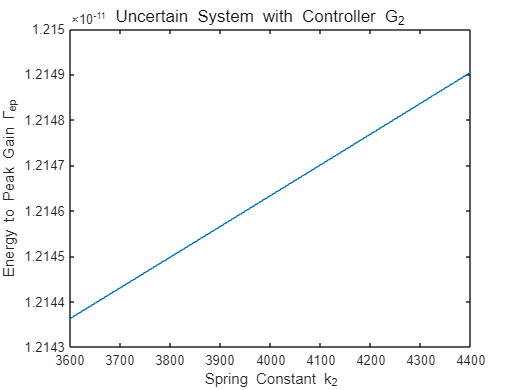

% Define uncertain system parameters
m1 = 20; % kg
m2 = 40; % kg
m3 = 30; % kg
k1 = 2000; % N/m
i = 1;
for k2 = 3600:1:4400 % N/m
    % Define the system matrices
    Ap = [0 0 0 1 0 0;
          0 0 0 0 1 0;
          0 0 0 0 0 1;
          -k1/m1 k1/m1 0 0 0 0;
          k1/m2 (-k1-k2)/m2 k2/m2 0 0 0;
          0 k2/m3 -k2/m3 0 0 0];
    Bp = [0; 0; 0; 1/m1; 0; 0];
    Dp = [0; 0; 0; 1/m1; 0; 0];
    Cp2 = [0 0 1 0 0 0];
    By2 = 0;
    Dy = 0;
    % Lumped system representation
    A = Ap;
    B = [Dp Bp];
    C = [zeros(size(Cp2)); Cp2];
    D = [Dy zeros(size(By2)); zeros(size(Dy)) By2];
    % Closed-loop system
    Acl = Ap + Bp*G2;
    Scl = ss(Acl, [Dp zeros(size(Bp))], C, D);
    h2_norm(i) = norm(Scl, 2);
    i = i+1;
end

figure;
sgtitle('Uncertain System with Controller G_2');
plot(3600:1:4400, h2_norm)
xlabel('Spring Constant k_2')
ylabel('Energy to Peak Gain Γ_ep')